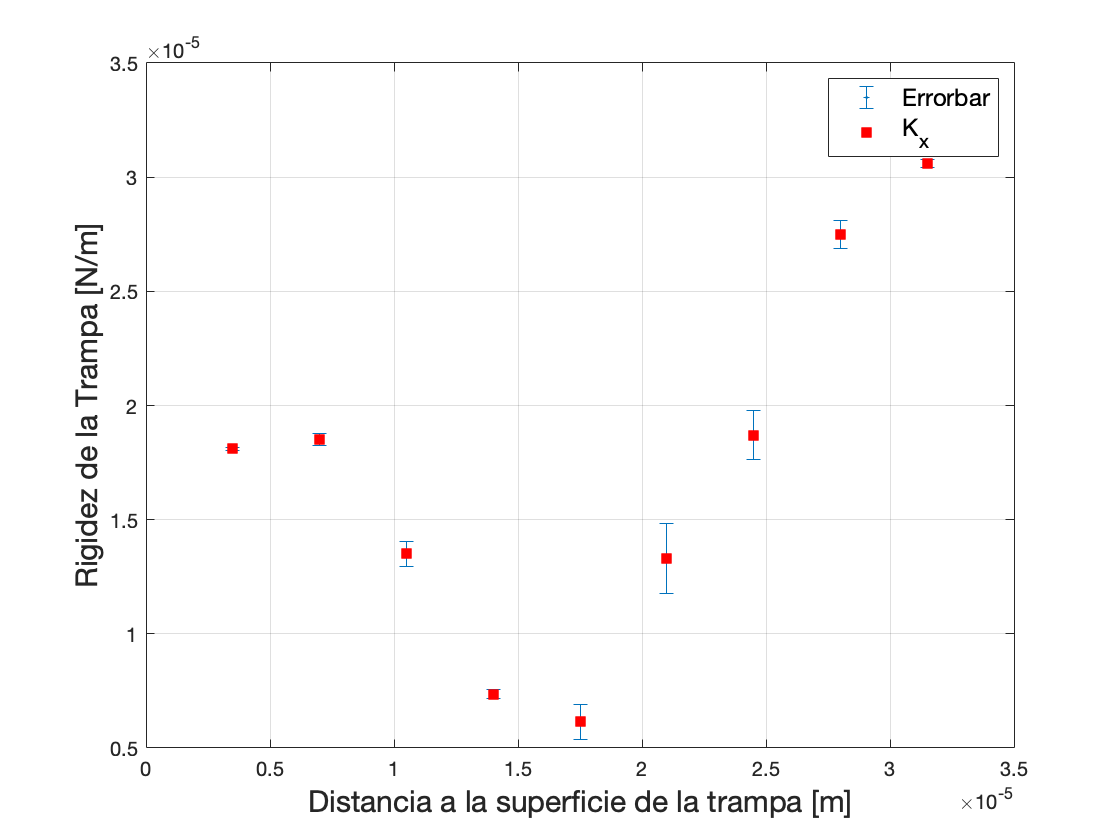

DatosK = readmatrix("k_x.txt");
d = DatosK(:,1);
k = DatosK(:,2);

c1 = 9.6e23;
c2 = -8.539e19;
c3 = 2.114e15;
c4 = 6.552e9;
c5 = -7.653e5;
c6 = 6.685;
c7 = 3.471e-6;
fk = c1*d.^6 + c2*d.^5 + c3*d.^4 +c4*d.^3 + c5*d.^2 + c6*d +c7;
er = abs(fk - k);

%%errorbar(d,fk,er,"o");
%%hold on
%%plot(d,k,"r.");
%%legend('Errorbar','K');

%%errorbar(d,fk,er,'-s','MarkerSize',1,...
    %%'MarkerEdgeColor','red','MarkerFaceColor','red')
    
errorbar(d,k,er,"*",'MarkerSize',1);
hold on 
plot(d,k,"s",'MarkerSize',6,'MarkerEdgeColor' ...
    ,'red','MarkerFaceColor','red');
legend('Errorbar','K_x','FontSize',12);
xlabel('Distancia a la superficie de la trampa [m]','FontSize',15);
ylabel('Rigidez de la Trampa [N/m]','FontSize',15);
grid on 